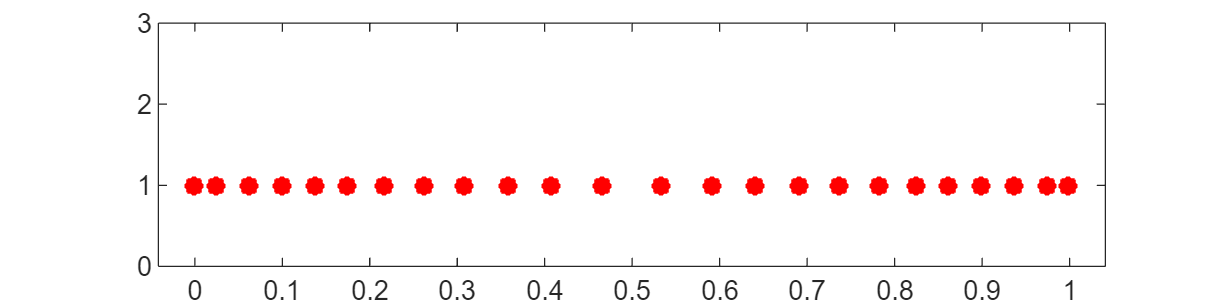

clear;clc;
set(0,'DefaultAxesFontName', 'Arial')
set(0,'DefaultAxesFontSize', 12)
% 
c = physconst("Lightspeed");
% freq params
f = 3e9; % 3 GHz
w = 2*pi*f;
f2 = 3.6e9; % 3 GHz
lam = freq2wavelen(f2);
k = 2*pi/lam;
% array params
dOk = lam/2;
xmin = 0;xmax = 23;
dxOk = dOk*(xmin:1:xmax)';
% tstar = dOk*([0.4 1.2 2 2.9 3.8 4.8 5.8 6.8 8 9.5 10.8 12.5])';
tstar = dOk*([0.8 2.2 3.4 4.6 5.7 6.8 7.8 8.7 9.6 10.5 11.4 12])';
dxOk = [-flipud(tstar);tstar];
dxOk = dxOk - min(dxOk);
ampsh = 1+ dxOk*0;
% ampsh = 0.3+(0.1*[11:-1:0])';
% ampsh = (0.3+0.1*[0:1:11])';
% ampsh = [flipud(ampsh);ampsh];
% ampsh = chebwin(24,24);


fig=figure(1);
fig.Position = [0 0 800 200];

plot(dxOk,ampsh,'r*','LineWidth',5)
axis([min(dxOk)-dOk max(dxOk)+dOk 0 3])

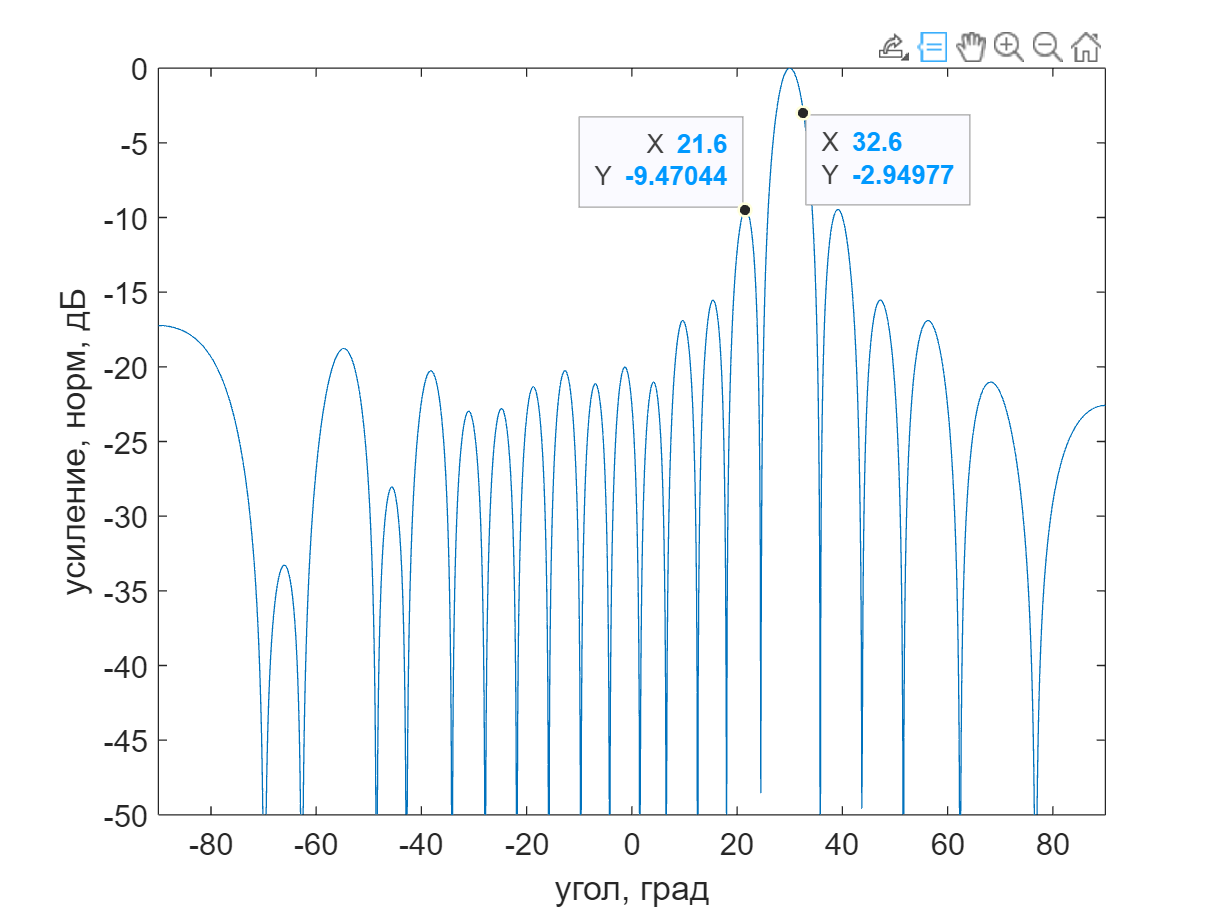

% set(gca,'visible','off')
% dxOk = dxOk - max(dxOk);
% % % specify aims
% aimAngles = [-10 0 45];
% aimAmps   = [ 0  0 0];
aimAngles = [30];
aimAmps   = [0];
% % % 
valuesOk = distribution_former(dxOk,f,aimAngles, aimAmps);
valuesOk = valuesOk.*ampsh;

[rstOk,theta] = aec_simulation(valuesOk, dxOk,f,0.1);
% % % 
rstOkT = mag2db(abs(rstOk));
rstOkT = rstOkT - max(rstOkT);
% rstOkT = db2pow(rstOkT);

fig=figure(2);
fig.Position = [0 0 800 600];
plot(theta, rstOkT)
ylabel("усиление, норм, дБ")
xlabel("угол, град")
axis([-90 90 -50 0])

[v,id]=max(rstOkT);
% % поиск УБЛ
[pks,locs] = findpeaks(rstOkT);
[~,pN]=sort(pks,'descend');
pN=pN(pN<pN(1));
pN=pN(1);
% % поиск -3дБ
[ d, ix ] = sort(abs(rstOkT+3),'ascend');
ix=ix(ix>id);
ix=ix(1);

ax2 = gca;
chart = ax2.Children(1);
datatip(chart,theta(locs(pN)),pks(pN),"Location","northwest");
datatip(chart,theta(ix),rstOkT(ix),"Location","southeast");



% title("\lambda/2")

% valuesOk = [zeros(993,1); valuesOk];
% res = fft(valuesOk);
% res = fftshift(res);
% res = pow2db(abs(res));
% res = res-max(res);
% sin_ls = linspace(sin(-pi/2),sin(pi/2),length(res));
% x_res = rad2deg(asin(sin_ls));
% figure(35);
% plot(x_res,res)

